In this sheet i have included the calculation of the Analytical Results of Rmiss distnace for both Q1 and Q2

For Q1, I faced issue of Rmiss was not matching with analytical one. actually analytical answer was corredt but in simulation i dint extracted the right data. now both are matching

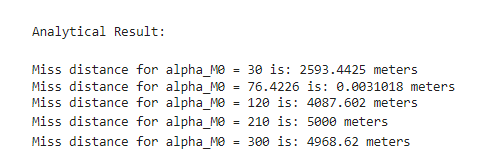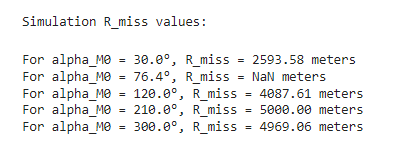

for Q2.  again i had a problem with miss distance calaculation i figured the equation idexing error and now it is matching.

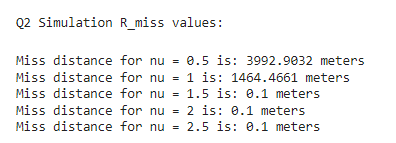

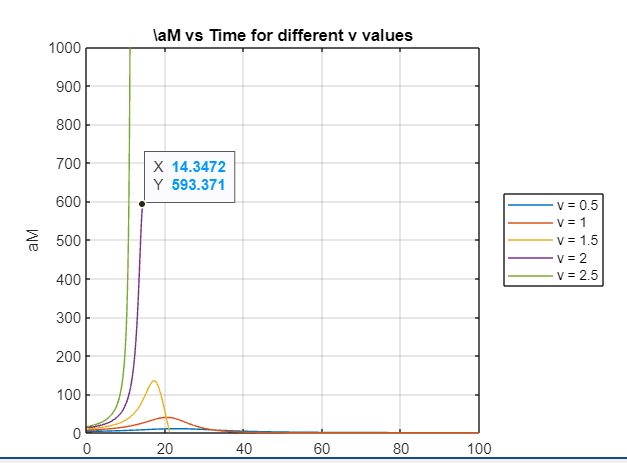  Lateral Accelartion for nu=2.5 going to >>infinity. , nu =2 >> 593.4(eventually it goes 0), reamning all other nu value  its going 0.

Q1) Analytical solution

clc;
clear all;
R0 = 5000; 
theta0 = deg2rad(30); 
V_M = 400; 
V_T = 300; 
alpha_T0 = deg2rad(135);

alpha_M0 = deg2rad([30, 76.4226, 120, 210, 300]);
V_R0 = zeros(1,5);
V_theta0 = zeros(1,5);
R_miss_anlytic = zeros(1,5);
fprintf('Q1 Analytical solution: ')

Q1 Analytical solution: 


for j = 1:5
    if alpha_M0(j) ~= deg2rad(210)
        V_theta0(j) = V_T * sin(alpha_T0 - theta0) - (V_M * sin(alpha_M0(j) - theta0));
        V_R0(j)  = V_T * cos(alpha_T0 - theta0) - (V_M * cos(alpha_M0(j) - theta0));   
        R_miss_anlytic(j) = R0 * (sqrt((V_theta0(j).^2/(V_R0(j).^2 + V_theta0(j).^2))));
        %fprintf('For alpha_M0 = %0.1f°, R_miss_anlytic = %0.2f meters\n', rad2deg(alpha_M0(j)), R_miss_anlytic(j));
        disp(['Miss distance for alpha_M0 = ',  num2str(rad2deg(alpha_M0(j))) , ' is: ', num2str(R_miss_anlytic(j)) , ' meters']);
    else
         disp(['Miss distance for alpha_M0 = ',  num2str(rad2deg(alpha_M0(j))) , ' is: ', num2str(R0) , ' meters']);
    end  
end

Miss distance for alpha_M0 = 30 is: 2593.4425 meters
Miss distance for alpha_M0 = 76.4226 is: 0.0031018 meters
Miss distance for alpha_M0 = 120 is: 4087.602 meters


Miss distance for alpha_M0 = 210 is: 5000 meters


Miss distance for alpha_M0 = 300 is: 4968.62 meters


Q2) analytical solution

clc;
clear all;
VT = 300;
alphaT0 = pi;
R0 = 10000;
theta0 = 45;
theta0 = deg2rad(theta0);
nu_values = [0.5, 1, 1.5, 2, 2.5];



K = zeros(1,5);
R_miss_q2 = zeros(1,5);
fprintf('Q2 Analytical solution: ')

Q2 Analytical solution: 

for i = 1:2

    K(i) = R0 * ( sin(alphaT0 - theta0))/(tan((alphaT0- theta0)/2))^nu_values(i);
    R_miss_q2(i) =  K(i)*(((tan(acos(nu_values(i))/2))^nu_values(i))/(sin(acos(nu_values(i)))));

    disp(['Miss distance for nu = ', num2str(nu_values(i)) , ' is: ', num2str(R_miss_q2(i)) , ' meters']);


end

Miss distance for nu = 0.5 is: 3992.8796 meters
Miss distance for nu = 1 is: NaN meters
